# Homework 4

## [✔] Problem 13.9: Determine the mean, ACVS and stationarity of a random process

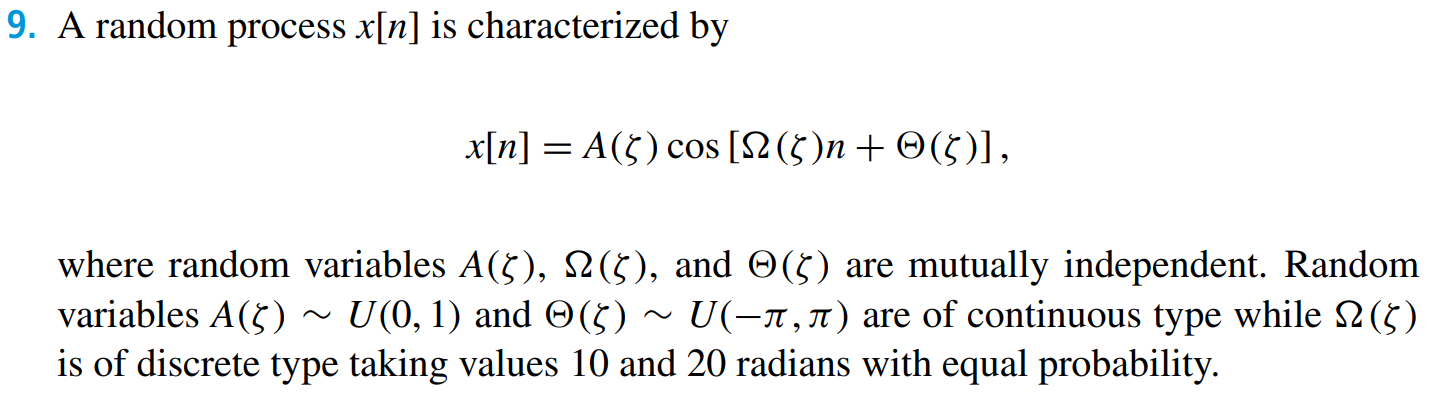

### a) Determine the mean sequence $m_x \left\lbrack n\right\rbrack$

We need to compute:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\;\mathrm{cos}\left(\Omega n+\Theta \right)\right\rbrack$$


Since the three random variables are independent then we can write:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\right\rbrack E\left\lbrack \;\cos \left(\Omega n+\Theta \right)\right\rbrack$$


We know that $E\left\lbrack A\right\rbrack =\frac{1}{2}$ since $A\sim U\left(0,1\right)$.

To find the expected value of a function, we need to compute the integral of the function weighted by density of the random quantity $f_{\Theta } \left(\Theta \right)$. Formally, we can write:


$$E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =\int_{-\pi }^{\pi } f_{\Theta } \left(\Theta \right)\cdot \cos \left(\Omega n+\Theta \right)\;d\Theta$$


Since $\Theta$ is uniform between $-\pi$ and $\pi$, the density is:


$$f_{\Theta } \left(\Theta \right)=\frac{1}{2\pi }$$


So the expection of the function becomes:


$$E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =\int_{-\pi }^{\pi } \frac{1}{2\pi }\cos \left(\Omega n+\Theta \right)\;d\Theta$$


We can bring out the constant outside the integral:


$$E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =\frac{1}{2\pi }\int_{-\pi }^{\pi } \cos \left(\Omega n+\Theta \right)\;d\Theta$$


The integral of $\mathrm{cos}\left(n\right)$ is $\mathrm{sin}\left(n\right)$ so we have:


$$E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =\frac{1}{2\pi }{\left\lbrack \mathrm{sin}\left(\Omega n+\Theta \right)\right\rbrack }_{-\pi }^{\pi } =\frac{1}{2\pi }\left\lbrack \mathrm{sin}\left(\Omega n+\pi \right)-\mathrm{sin}\left(\Omega n-\pi \right)\right\rbrack$$


Looking up the trigonometric identities:

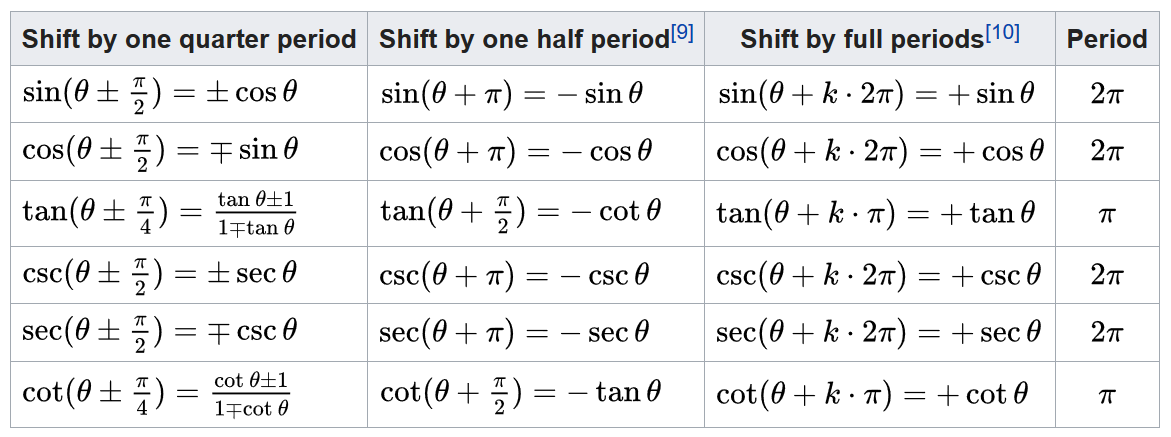

We see that $\mathrm{sin}\left(\Omega n+\pi \right)=-\mathrm{sin}\left(\Omega n\right)$ and $-\mathrm{sin}\left(\Omega n-\pi \right)=\mathrm{sin}\left(\Omega n\right)$. Substituting these identities we get:


$$E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =\frac{1}{2\pi }\left\lbrack -\mathrm{sin}\left(\Omega n\right)+\sin \left(\Omega n\right)\right\rbrack =0$$


Therefore: $E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =0$

We can visualise why the expected value of $\cos \left(\Omega n+\Theta \right)$ is zero.

Suppose we want to compute $E\left\lbrack \mathrm{cos}\left(\Omega n+\Theta \right)\right\rbrack$ where $\Theta \sim U\left(-\pi ,\pi \right)$. Let us pick one frequency $\omega$ (realise one value of $\Omega$). Then let us pick a lot of realisations of $\Theta$. Now if we plot the function $\mathrm{cos}\left(\omega \;n+\theta \right)$ for different values of $\theta$ then we will see something like this:

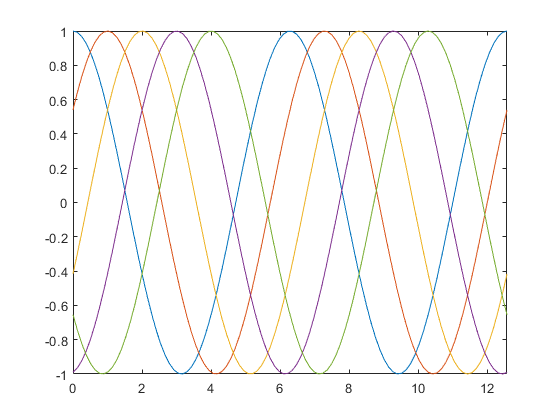

n = linspace(0, 4*pi);
plot(n, cos(n), n, cos(n-1), n, cos(n-2), n, cos(n-3), n, cos(n-4));
xlim([0, 4*pi]);

If we plot hundreds of cosine functions shifted slightly, we get a large blob of points from -1 to 1. For this reason, the quantity $E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack$ will be zero because the mean value is 0.

In signal processing, we like to add random shifts ala $\Theta \sim U\left(0,2\pi \right)$ to avoid that the expected value or the mean value becomes dependent on time. 

### b) Determine the autocovariance sequence ACVS $c_X \left\lbrack m,n\right\rbrack$

The ACVS provides a measure of the linear dependence between the values of a random process at two different times. In this sense, it determines how quickly the signal amplitude changes from sample to sample (time variation).

To compute the autocovariance sequence, we use the following equation:

 

The formula relates the cross-correlation $r_{\mathrm{xy}} \left\lbrack n,m\right\rbrack$ and cross-covariance $c_{\mathrm{xy}} \left\lbrack n,m\right\rbrack$. It states that the cross-correlation is the cross-covariance added with the product of the means of the two signals.

From a) we know that the expected value (mean) of the given random process is zero. This essentially means that the cross-correlation and the cross-covariance are the same.

This is also clear from the definition of the cross-covariance and cross-correlation.

The cross-covariance for a random process defined as:


$$c_{\mathrm{xy}} \left\lbrack n,m\right\rbrack =E\left\lbrace \left(x\left\lbrack n\right\rbrack -E\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace \right)\left(y\left\lbrack m\right\rbrack -E\left\lbrace y\left\lbrack m\right\rbrack \right\rbrace \right)\right\rbrace$$


The cross-correlation for a random process is defined as:


$$r_{\mathrm{xy}} \left\lbrack n,m\right\rbrack =E\left\lbrace x\left\lbrack n\right\rbrack y\left\lbrack m\right\rbrack \right\rbrace$$


*The term “auto” comes about because the two random variables are taken from the same process.*

Note that when $E\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =E\left\lbrace y\left\lbrack m\right\rbrack \right\rbrace =0$ then $c_{\mathrm{xy}} \left\lbrack n,m\right\rbrack =r_{\mathrm{xy}} \left\lbrack n,m\right\rbrack$.

syms A
f = A^2;
int(f, A, 0, 1)

$$ans = \frac{1}{3}$$

The result from the solution set:

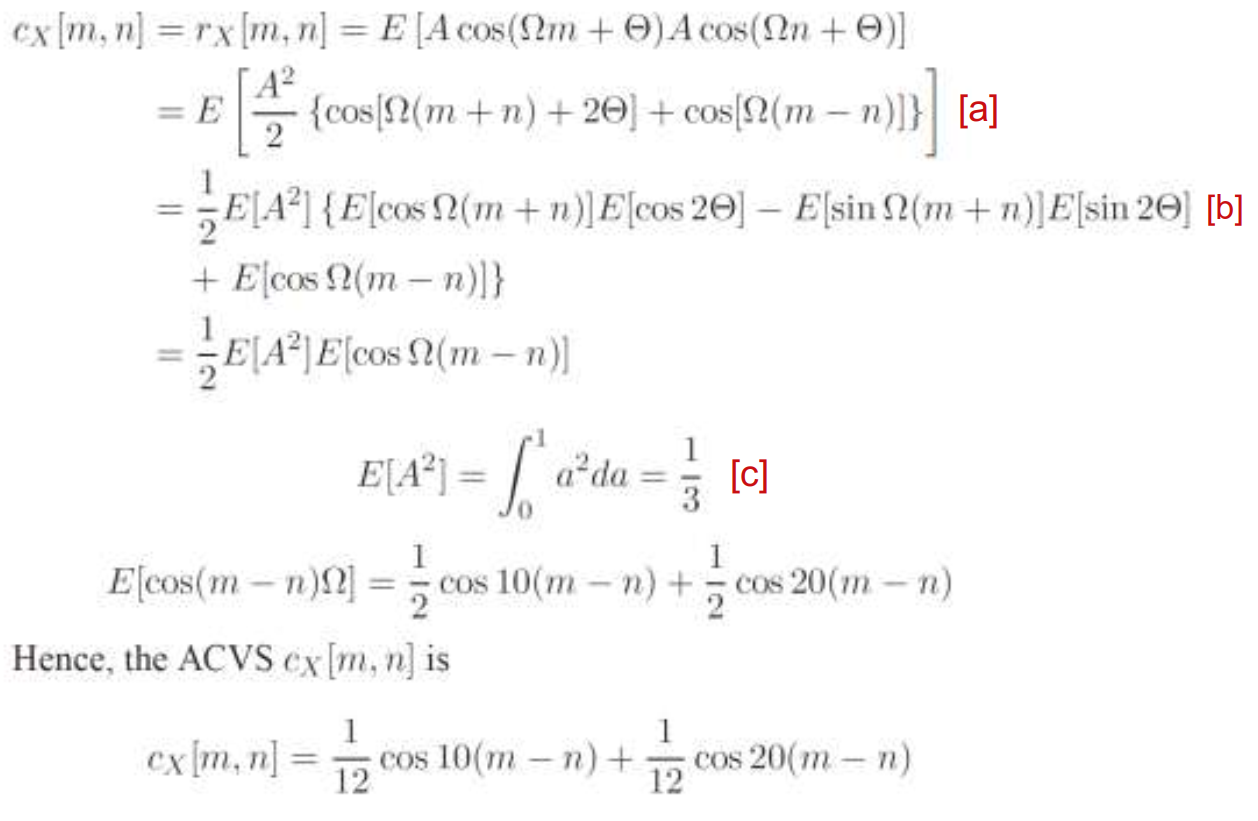

Following identities were used in the solution:

[a] $\mathrm{cos}\left(\alpha \right)\mathrm{cos}\left(\beta \right)=\frac{1}{2}\left(\mathrm{cos}\left(\alpha +\beta \right)+\mathrm{cos}\left(\alpha -\beta \right)\right)$

[b] $\mathrm{cos}\left(\alpha +\beta \right)=\mathrm{cos}\left(\alpha \right)\mathrm{cos}\left(\beta \right)-\mathrm{sin}\left(\alpha \right)\mathrm{sin}\left(\beta \right)$

[c] $E\left\lbrack X^n \right\rbrack =\int_{-\infty }^{\infty } x^n \cdot f_X \left(x\right)\;\mathrm{dx}$

### 👀 c) Comment on the stationarity of the random process

First, let us defined what the stationarity of a random process is.

A random process is said to be stationary if its characteristics does not change over time. This means that:

i) The mean and the variance of the process is constant:

ii) The auto-correlation and auto-covariance only depend on the lag $\ell$:

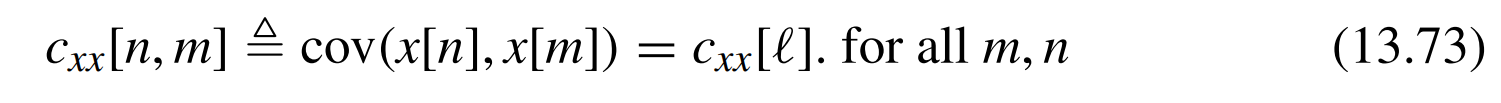

If a random process fulfills both requirements, then it is said to be wide-sense stationary. 

In a) we showed the mean of the process is zero.

In b) we showed that the autocovariance only depends on $n$ and $m$, **which we assume is the lag**.

Therefore, we can conclude that the random process $x\left\lbrack n\right\rbrack$ is stationary.

## [✔] Problem 13.13: MSE objective function

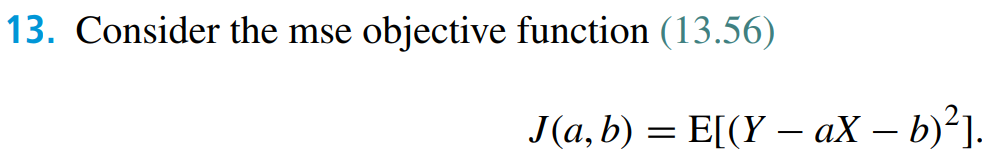

### a) Express the objective function in terms of its parameters

Use MATLAB to expand the expression inside the expected value:

syms a b X Y
expand((Y-a*X - b)^2)

$$ans = X^{2}\,a^{2}-2\,X\,Y\,a+2\,X\,a\,b+Y^{2}-2\,Y\,b+b^{2}$$

So we have:


$$J\left(a,b\right)=E\left\lbrack X^2 a^2 -2\;X\;Y\;a+2\;X\;a\;b+Y^2 -2\;Y\;b+b^2 \right\rbrack$$


Let $X$ and $Y$ be two random variables and $a$ and $b$ be two constants. Following expectation identities apply:

- $E\left\lbrack a\right\rbrack =a$               e.g. $E\left(42\right)=42$

- $E\left\lbrack a\;X\right\rbrack =a\;E\left\lbrack X\right\rbrack$   e.g. if you multiply every value by 2, the expectation doubles

- $E\left\lbrack a\pm X\right\rbrack =a\pm E\left\lbrack X\right\rbrack$ e.g. if you add 42 to every case, the expectation increases by 42

- 
$$E\left\lbrack X+Y\right\rbrack =E\left\lbrack X\right\rbrack +E\left\lbrack Y\right\rbrack$$


- If $X$ and $Y$ are independent, then $E\left\lbrack \mathrm{XY}\right\rbrack =E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack$

Use rule 4:


$$\begin{array}{l}
J\left(a,b\right)=E\left\lbrack X^2 a^2 -2\;X\;Y\;a+2\;X\;a\;b+Y^2 -2\;Y\;b+b^2 \right\rbrack \\
J\left(a,b\right)=E\left\lbrack X^2 a^2 \right\rbrack -E\left\lbrack 2\;X\;Y\;a\right\rbrack +E\left\lbrack 2\;X\;a\;b\right\rbrack +E\left\lbrack Y^2 \right\rbrack -E\left\lbrack 2\;Y\;b\right\rbrack +E\left\lbrack b^2 \right\rbrack 
\end{array}$$


Use rule 1 and rule 2:


$$J\left(a,b\right)=a^2 E\left\lbrack X^2 \right\rbrack -2\;a\;E\left\lbrack \;X\;Y\right\rbrack +2\;a\;b\;E\left\lbrack X\right\rbrack +E\left\lbrack Y^2 \right\rbrack -2\;b\;E\left\lbrack Y\right\rbrack +b^2$$


### b) Using partial derivatives to determine the values of parameters

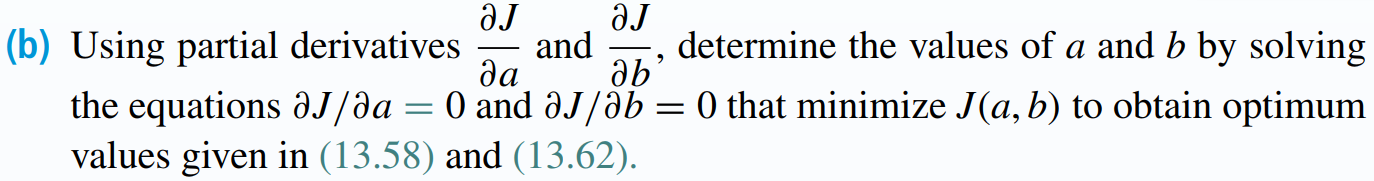

First, take the partial derivatives:


$$\frac{\partial \;J\left(a,b\right)}{\partial \;a}=2a\;E\left\lbrack X^2 \right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;b\;E\left\lbrack X\right\rbrack$$
 


$$\frac{\partial \;J\left(a,b\right)}{\partial \;b}=2\;a\;E\left\lbrack X\right\rbrack -2\;E\left\lbrack Y\right\rbrack +2b$$


Next, solve the equations:

(Eq. 1) $2a\;E\left\lbrack X^2 \right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;b\;E\left\lbrack X\right\rbrack =0$

(Eq. 2) $2\;a\;E\left\lbrack X\right\rbrack -2\;E\left\lbrack Y\right\rbrack +2b=0$

Isolate $b$ in (Eq. 2):


$$\begin{array}{l}
2b=-2\;a\;E\left\lbrack X\right\rbrack +2\;E\left\lbrack Y\right\rbrack \\
b=-a\;E\left\lbrack X\right\rbrack +E\left\lbrack Y\right\rbrack \\
b=E\left\lbrack Y\right\rbrack -a\;E\left\lbrack X\right\rbrack 
\end{array}$$


This corresponds to (13.58) in the book:

Now, plug the expression for $b$ into Eq. 1 in order to find an expression for $a$:


$$\begin{array}{l}
2a\;E\left\lbrack X^2 \right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;b\;E\left\lbrack X\right\rbrack =0\\
2a\;E\left\lbrack X^2 \right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;\left(E\left\lbrack Y\right\rbrack -a\;E\left\lbrack X\right\rbrack \right)\;E\left\lbrack X\right\rbrack =0\\
2a\;E\left\lbrack X^2 \right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack \;-2\;a\;E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack =0\\
2a\;E\left\lbrack X^2 \right\rbrack -2\;a\;E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack \;=0\\
2a\left(\;E\left\lbrack X^2 \right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack \right)-2\;E\left\lbrack X\;Y\right\rbrack +2\;E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack \;=0\\
2a\left(\;E\left\lbrack X^2 \right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack \right)=2\;E\left\lbrack X\;Y\right\rbrack -2\;E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack \;\\
a\left(\;E\left\lbrack X^2 \right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack \right)=E\left\lbrack X\;Y\right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack \;\\
a=\frac{\;E\left\lbrack X\;Y\right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack }{E\left\lbrack X^2 \right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack }=\frac{\;E\left\lbrack X\;Y\right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack }{E\left\lbrack X^2 \right\rbrack -{E\left\lbrack X\right\rbrack }^2 }
\end{array}$$


We have found an expression for $a$. The numerator looks like it is the covariance:

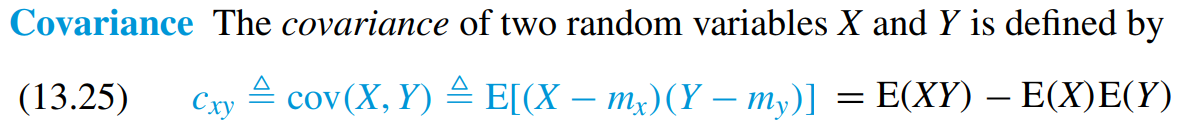

The denominator looks like it is the variance:

(13.11)     $\textrm{var}\left(X\right)=E\left\lbrack X^2 \right\rbrack -{E\left\lbrack X\right\rbrack }^2 =E\left\lbrack X^2 \right\rbrack -m_x^2$

Therefore, the derived expression is the same as (13.62) in the book.

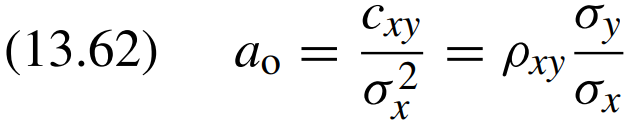

## [✔] Problem 13.22: Computing distributions

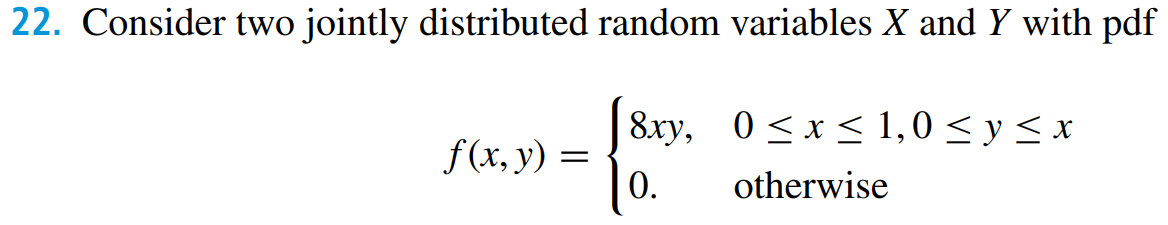

### 👀 a) Determine marginal distributions and conditional probabilities

The **marginal** distributions of random variables $X$ and $X$ are obtained by integration as follows:  

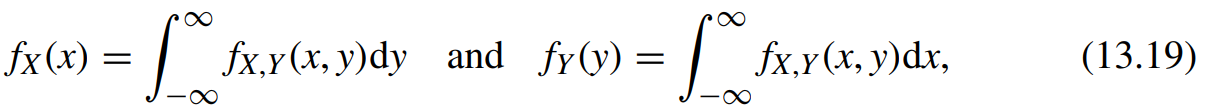

Compute the marginal distribution of $X$:


$$f\left(x\right)=\int_{-\infty }^{\infty } f\left(x,y\right)\;\mathrm{dy}=\int_0^x 8xy\;\mathrm{dy}={\left\lbrack \frac{1}{2}8xy^2 \right\rbrack }_0^x =\frac{1}{2}8xx^2 -0=4x^3 \;\mathrm{where}\;0\le x\le 1$$
 

Compute the marginal distribution of $Y$:


$$f\left(y\right)=\int_{-\infty }^{\infty } f\left(x,y\right)\;\textrm{dx}=\int_y^1 8xy\;\textrm{dx}={\left\lbrack 4yx^2 \right\rbrack }_y^1 =4y-4y^3 \;\mathrm{where}\;0\le y\le 1$$


To compute $f\left(x|y\right)$ we use following relation:

From Eq. 13.23, we know that:


$$f\left(x|y\right)=\frac{f\left(x,y\right)}{f\left(y\right)}=\frac{8\mathrm{xy}}{4y-4y^3 }=\frac{4y\cdot 2x}{4y\left(1-y^2 \right)}=\frac{2x}{1-y^2 }$$


and 


$$f\left(y|x\right)=\frac{f\left(x,y\right)}{f\left(x\right)}=\frac{8x\;y}{4x^3 }=\frac{4x\cdot 2y}{4x\cdot x^2 }=\frac{2y}{x^2 }$$


### b) Are X and Y independent?

Random variables $X$ and $Y$ are statistically independent, if $f\left(y|x\right)=f\left(y\right)$ or $f\left(x|y\right)=f\left(x\right)$.

In a) we have computed the following expressions:

- 
$$f\left(x\right)=4x^3$$


- 
$$f\left(y\right)=4y-4y^3 \;$$


- 
$$f\left(y\left|x\right.\right)=\frac{2y}{x^2 }$$


- 
$$f\left(x\left|y\right.\right)=\frac{2x}{1-y^2 }$$


Clearly$f\left(y|x\right)\not= f\left(y\right)\;\mathrm{and}\;f\left(x|y\right)\not= f\left(x\right)$. Therefore, the answer is no! The random variables $X$ and $Y$ are not statistically independent.

## [✔] ADSI Problem 4.1: Poisson distribution

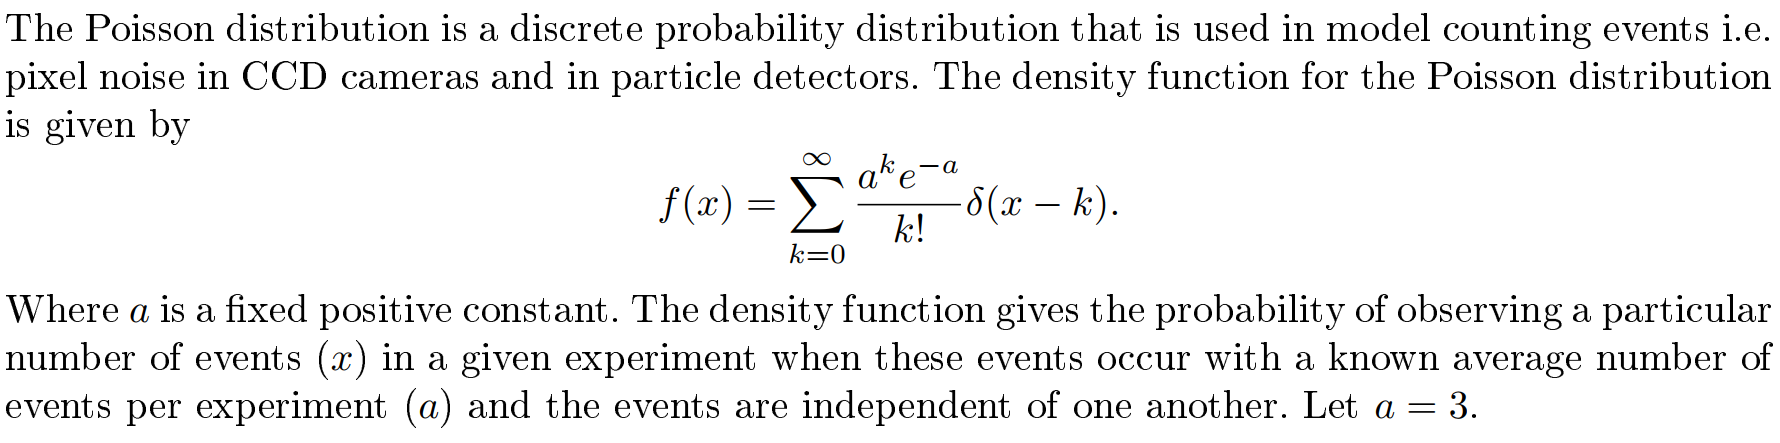

### 1) Sketch the density function

Use MATLAB to plot the density function. The probability mass function for the poisson distribution is:


$$f\left(k\right)=\frac{a^k }{k!}\mathrm{exp}\left(-a\right)$$


x = 0:10;
a = 3;
f = @(k) (exp(-a) * a.^k)/factorial(k);
%stem(x, f(x))
% applies the function f to the elements of x
y = arrayfun(f, x);
stem(x, y);
xlabel("Number of events x")
ylabel("Probability of observation f(x)")

### 2) Calculate the probability of measuring 4 or 5 events in an experiment.

When we measure, we cannot get both 4 and 5 at the same time. This means that the event of measuring 4 and the event of measuring 5 are mutually exclusive since these two events cannot happen at the same time.

Therefore, the probability that one of the mutually exclusive events occur is the sum of their individual probabilities.


$$\mathrm{Pr}\left(x=4\;\mathrm{or}\;x=5\right)=\mathrm{Pr}\left(x=4\right)+\mathrm{Pr}\left(x=5\right)=f\left(4\right)+f\left(5\right)$$


f(4)+f(5)

Final answer is: $\mathrm{Pr}\left(x=4\;\mathrm{or}\;x=5\right)=0\ldotp 2689$

### 3) Calculate the probability of measuring 3 or more events in an experiment. 

To compute the probability of measuring 3, or more events:


$$\mathrm{Pr}\left(x\ge 3\right)=\sum_{k=3}^{\infty } f\left(k\right)$$


Since we have an infinite sum, it is a bit difficult to compute. Instead, we can use on the fact that the sum over the mass function is 1. This means that we only need to compute the probabilites of $1-\left(f\left(0\right)+f\left(1\right)+f\left(2\right)\right)$ is the same as computing the infinite sum:


$$\mathrm{Pr}\left(x\ge 3\right)=1-\sum_{k=0}^2 f\left(k\right)$$


Let us do it in MATLAB:

1-(f(0) + f(1) + f(2))

The final answer is: $\mathrm{Pr}\left(x\ge 3\right)=0\ldotp 5768$

## [✔] Lecture problem: find the probability density function from a signal

For this problem we will use two random variales.

The random variable $X_0$ tells us the value of a signal at time $t_0$ whereas $X_1$ tells us the value of the same signal at time $t_{0\;} +1$i.e., one time unit later. We are making two measurements at the same signal.

We use a generic formula for the joint PDF:


$$f_{X_0 ,X_1 } \left(x_0 ,x_1 \right)=p_0 \delta \left\lbrack x_0 +1\right\rbrack \delta \left\lbrack x_1 +1\right\rbrack +p_1 \delta \left\lbrack x_0 +1\right\rbrack \delta \left\lbrack x_1 -1\right\rbrack +p_2 \delta \left\lbrack x_0 -1\right\rbrack \delta \left\lbrack x_1 +1\right\rbrack +p_3 \delta \left\lbrack x_0 -1\right\rbrack \delta \left\lbrack x_1 -1\right\rbrack$$


where:

- $p_0$ is the probability that if the signal is +1 at then it will remain +1 at $t_0 +1$

- $p_1$ is the probability that if the signal is +1 at then it will change -1 at $t_0 +1$

- $p_2$ is the probability that if the signal is -1 at then it will change +1 at $t_0 +1$

- $p_3$ is the probability that if the signal is -1 at then it will remain -1 at $t_0 +1$

At each given signal, we make two measurements and see what is the likelihood that the signal will remain the same or change.

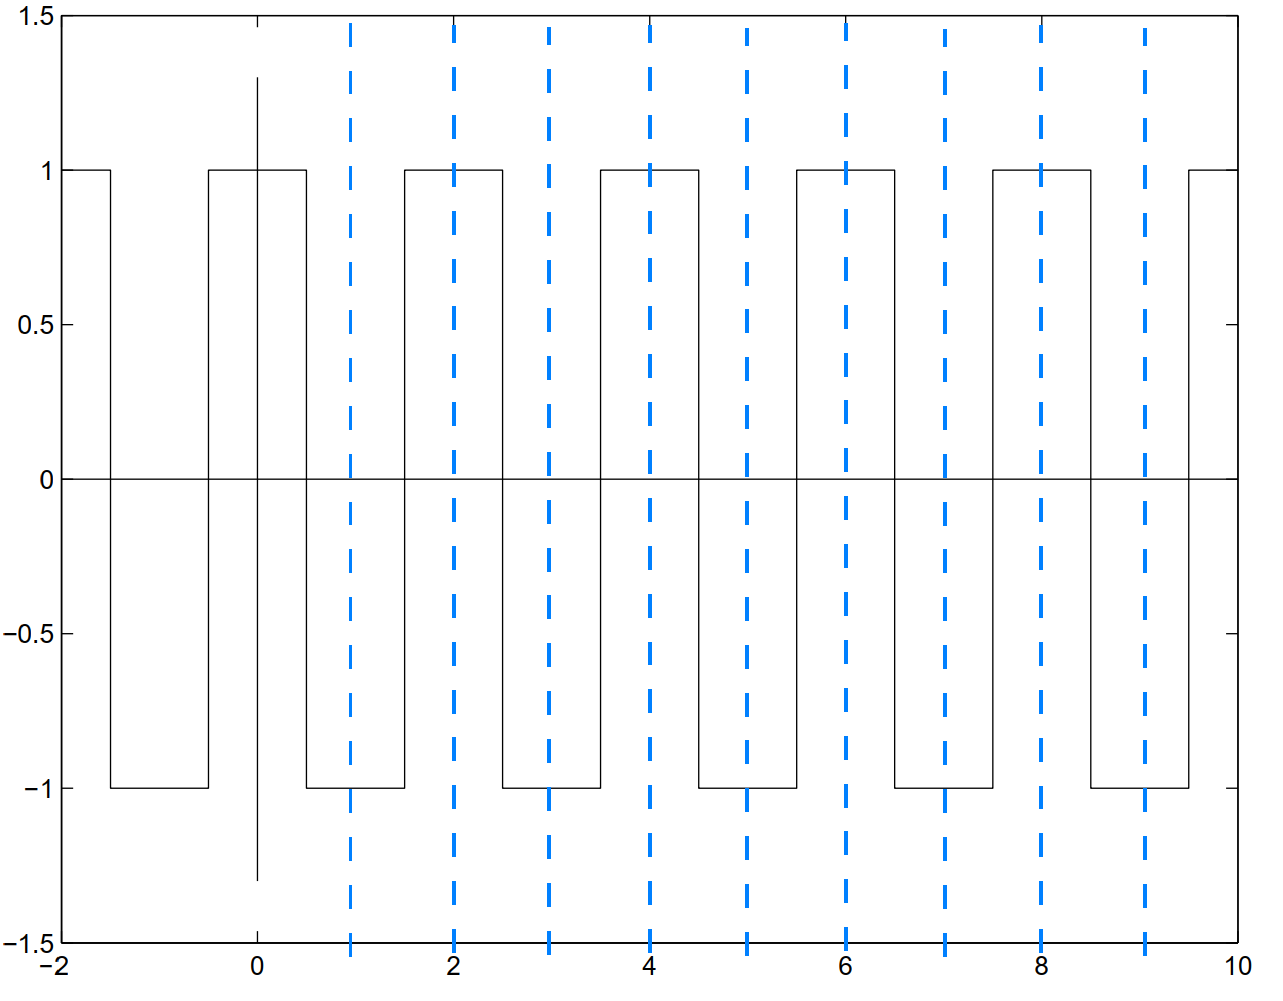

From the signal above, we make following observations:

- $p_0 =0$ because we never observe that when the signal is +1 at time $t_0$ then it will remain +1 at time $t_0 +1$

- $p_1 =0\ldotp 5$ because we observe that when the signal is +1 at time $t_0$ then it always changes to -1 at time $t_0 +1$. 

- $p_2 =0\ldotp 5$ because when the signal is -1 at $t_0$ then it flips to +1 at $t_0 +1$

- $p_3 =0$ because we never observe that when the signal is -1 at time $t_0$ then it will remain -1 at time $t_0 +1$

Thus, the joint PDF for square signal is:


$$f_{X_0 ,X_1 } \left(x_0 ,x_1 \right)=\frac{1}{2}\delta \left\lbrack x_0 +1\right\rbrack \delta \left\lbrack x_1 -1\right\rbrack +\frac{1}{2}\delta \left\lbrack x_0 -1\right\rbrack \delta \left\lbrack x_1 +1\right\rbrack$$


Another more interesting problem is the signal below:

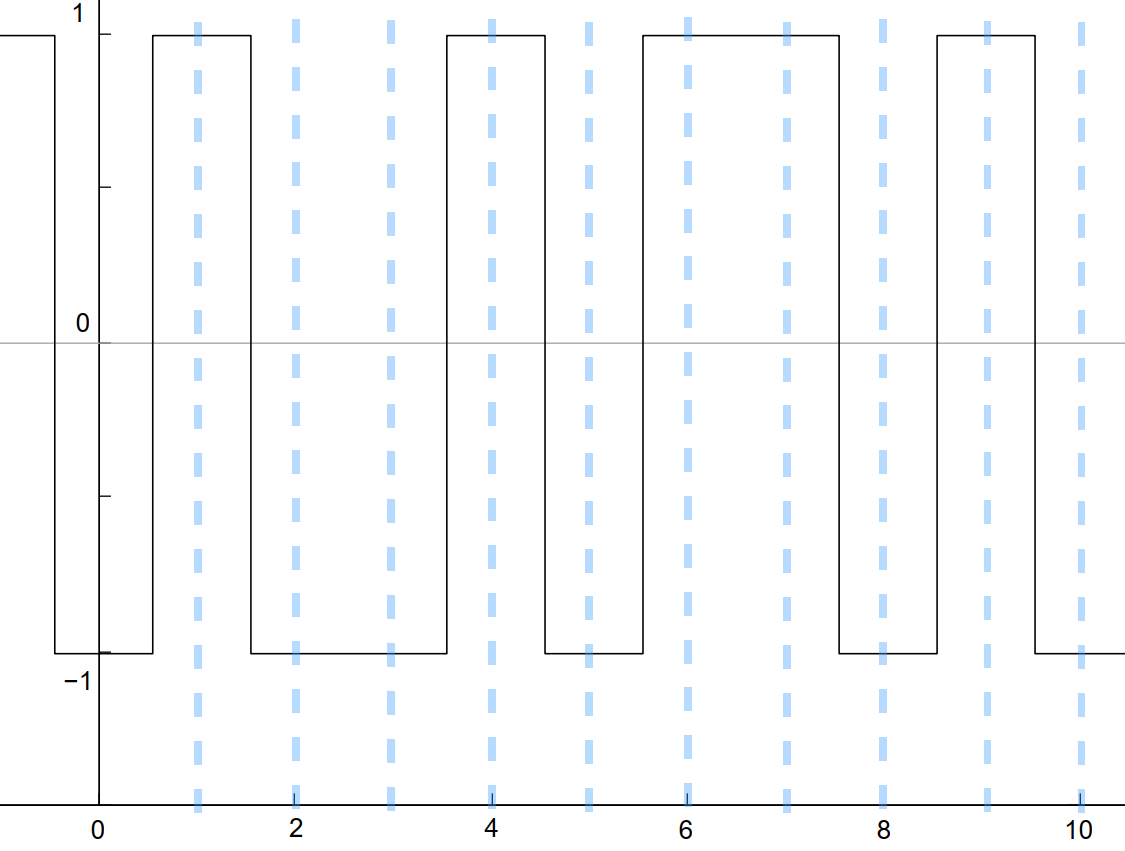

This is a short realisation so it is difficult to find the likelihoods by looking at the signal alone.

## [✔] ADSI Problem 4.3: Random process

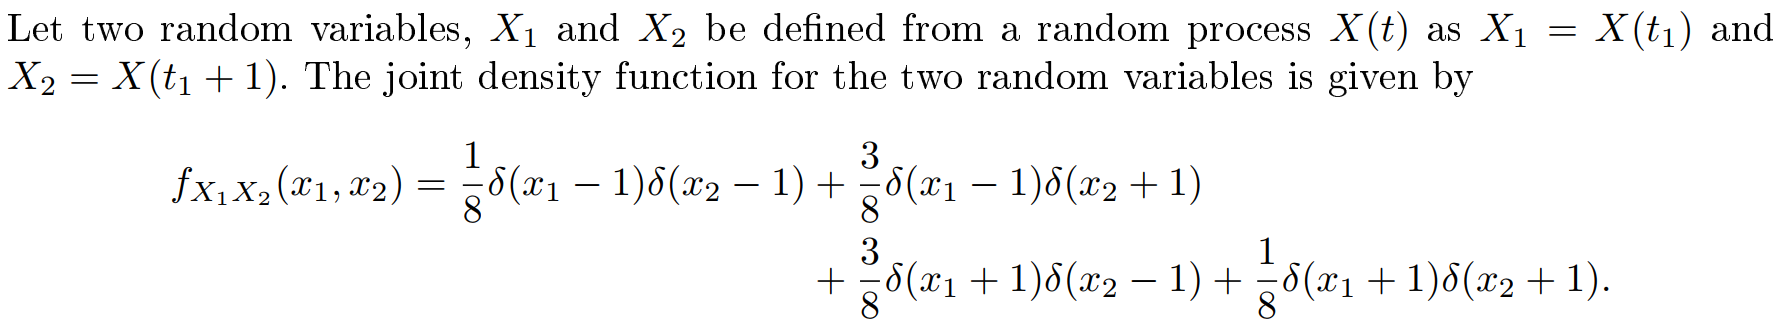

The random variable $X_1$ tells us the value of a signal at time $t_1$ whereas $X_2$ tells us the value of the same signal at time $t_{1\;} +1$i.e., one time unit later. We are making two measurements at the same signal. 

### 1) Draw a realisation of a random process

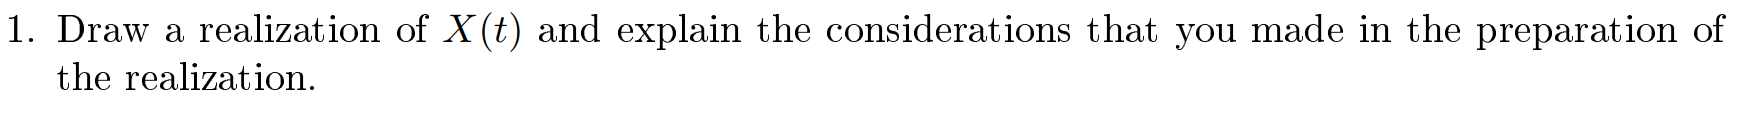

From the $\delta$ functions, we see that the signal can only take on two values: -1 and +1. This means that the realisation of the random process $X\left(t\right)$ flips between -1 and +1 i.e., $X\left(t\right)\in \left\lbrace -1,1\right\rbrace$. 

From each term we can read off the likelihood of the behaviour of the signal.

- If the signal is +1 at $t_1$ then there is 1/8 probability that the signal will remain +1 at $t_1 +1$

- If the signal is +1 at $t_1$ then there is 3/8 probability that the signal will change to -1 at $t_1 +1$

- If the signal is -1 at $t_1$ then there is 3/8 probability that the signal will change to +1 at $t_1 +1$

- If the signal is -1 at $t_1$ then there is 1/8 probability that the signal will remain at -1 at $t_1 +1$

This means that during a time window of 8 time units, the signal will be behave as follows:

- Given time $t_0$ when signal is +1, only once will the signal remain +1 at next time unit

- Given time $t_0$ when signal is +1, three of the times the signal changes to -1 at next time unit

- Given time $t_0$ when signal is -1, three of the times the signal changes to +1 at next time unit

- Given time $t_0$ when signal is -1, only once will the signal remain -1 at next time unit

Thus, one realisation of the random process is as follows:

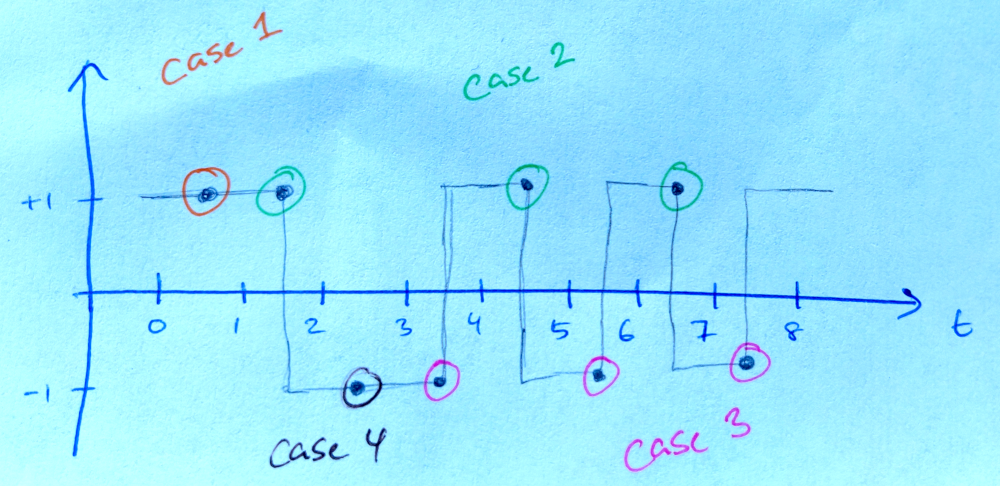

Another realisation of the random process is as follows:

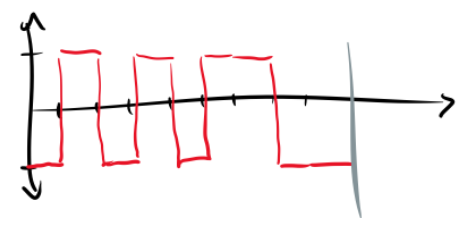

### 2) Determine whether the random process is deterministic or non-deterministic

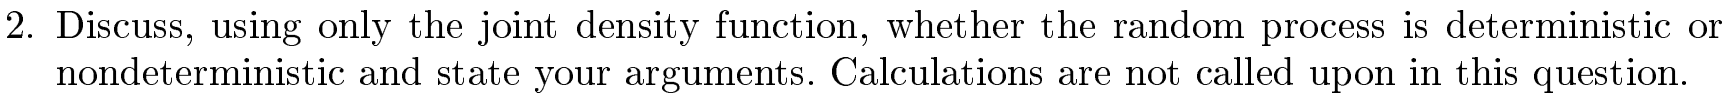

At each given time instant $t_0$ the likelihood of the signal value changing sign at next time unit (either from +1 to -1 or from -1 to +1) is $\frac{6}{8}=\frac{3}{4}$.

And the likelihood of the signal value remaining the same is $\frac{2}{8}=\frac{1}{4}$. 

So the joint probability density function only tells us that the signal will change sign or stay the same with some probability.

However, it does not say at what time instant the signal remain the same and at what time instants the signal will change. 

Therefore, the random process is non-deterministic. 

*NOTE! *We can make rather educated guesses for the next value of the signal so it wouldn't be completely unjustified to denote the signal as 'semi'-deterministic.

### 3) Plot realisations of the random process in MATLAB

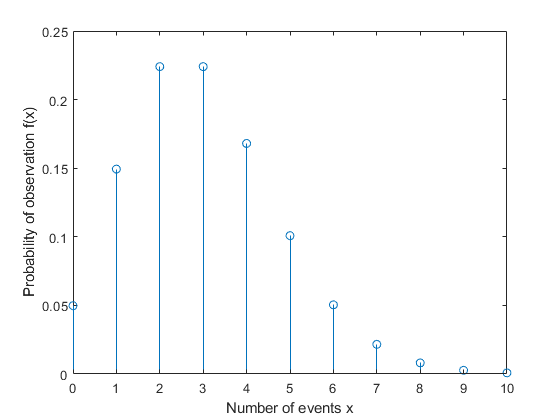

p0=1/8;
p1=3/8;
p2=3/8;
p3=1/8;

POS_VAL = 1;
NEG_VAL = -1;


N = 50;
x = zeros(1, N);

x(1) = 1; % Keep it simple. Could be 50% probability of -1 or 1.

ans = 0.2689

for i = 2:N-1
    if x(i-1) == POS_VAL
        if rand < p0
            x(i) = POS_VAL; % With probability p0, nothing changes
        else
            x(i) = NEG_VAL; % With probability p1, flip the sign
        end
    elseif x(i-1) == NEG_VAL
        if rand < p2

ans = 0.5768

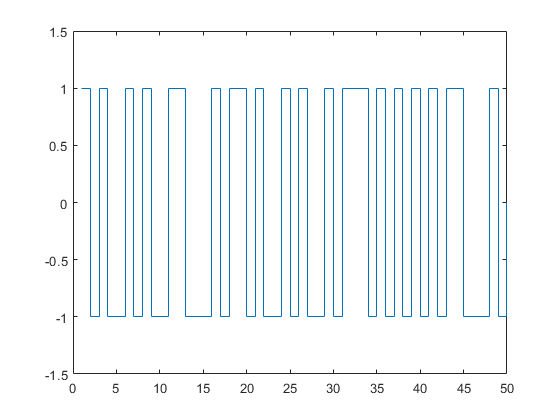

            x(i) = NEG_VAL; % With probability p2, nothing changes
        else
            x(i) = POS_VAL; % With probability p3, flip the sign
        end
    else
        display("Something is wrong!")
        x(i) = 2
    end
end

% x(1) = 1;
%for i = 2:N-1
% x(i) = x(i-1)*(2*(randi(4)==1)-1); %1/4 chance that sign stays the same
%end

stairs(x);
ylim([-1.5, 1.5]);